% Define the Laplace variable
s = tf('s'); 

% Define the transfer function matrix G(s)
G = [
    1.0 / (100*s + 1),  0.3 / (10*s + 1);
   -0.4 / (10*s + 1),  2.0 / (100*s + 1)
]

G =
 
  From input 1 to output...
           1
   1:  ---------
       100 s + 1
 
         -0.4
   2:  --------
       10 s + 1
 
  From input 2 to output...
         0.3
   1:  --------
       10 s + 1
 
           2
   2:  ---------
       100 s + 1
 
Continuous-time transfer function.
Model Properties



% ----- Static RGA Calculation (s = 0) -----
% Evaluate G(s) at s = 0 to get the steady-state gain matrix
G_static = evalfr(G, 0);

% Calculate the static RGA matrix
RGA_static = real(G_static .* inv(G_static)');  % Take the real part
% Display the static RGA matrix
disp('Static RGA Matrix (s = 0):');

Static RGA Matrix (s = 0):


RGA_static

RGA_static =     0.9434    0.0566
    0.0566    0.9434


### Dynamic RGA calcualtion using Singular Value Decomposition (SVD)

The **singular values** of each individual element of the transfer function matrix G(i,j)G(i,j)G(i,j) are computed across the frequency range ω. The `sigma` function is used to compute the singular values σ(G(i,j),ω).

For each frequency ω\omegaω, the singular value matrix KpK_pKp� is computed, and the RGA is calculated as: 


$$\mathrm{RGA}\left(\omega \right)=\mathrm{Kp}\left(\omega \right)\odot \left(\mathrm{Kp}\left(\omega {\left.\right)}^{-1} {\left.\right)}^T \right.\right.$$


Where:

- Kp(ω) is the matrix of singular values at frequency ω\omegaω.

- ⊙ denotes element-wise multiplication.

- The RGA is calculated based on the **singular value approximation** of the transfer function matrix.

Ths method provides a **simplified approach** to dynamic RGA using singular values, which are easier to compute and less prone to numerical issues. It avoids directly inverting the full transfer function matrix at each frequency, which can be advantageous for larger systems or ill-conditioned matrices.

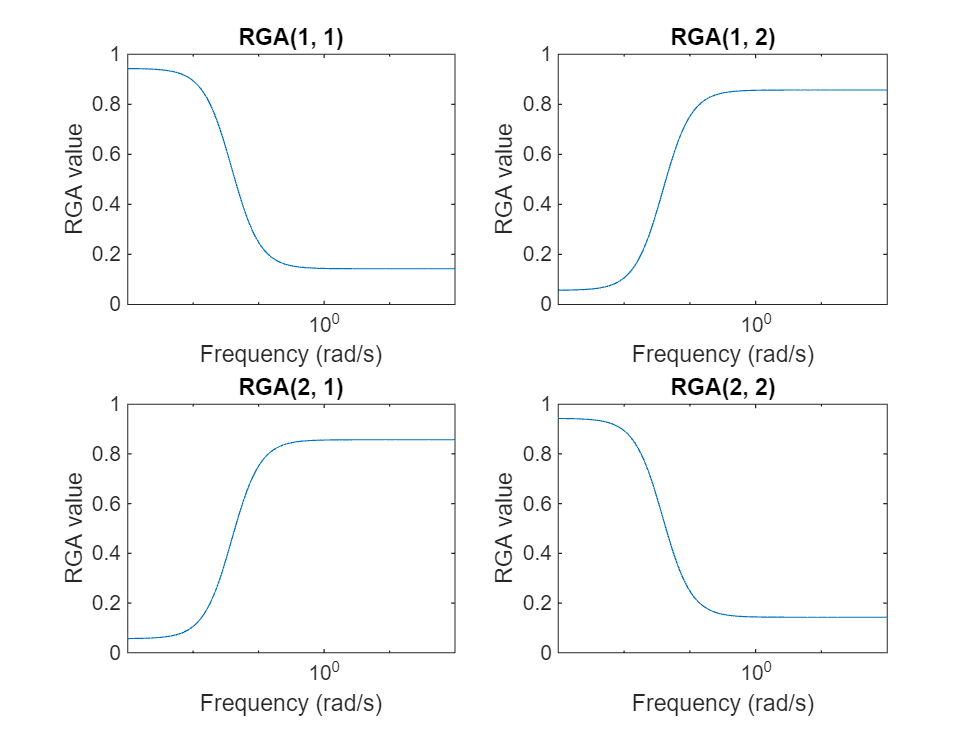

% Define the frequency range
w = logspace(-3, 2, 100);  % From 0.001 to 100 rad/s

% Get the steady-state (s = 0) gain matrix
K = dcgain(G);   % dcgain calculates the static gain of the system

% Get the sign of the static gain matrix to account for directionality
Ksgn = sign(K);

% Preallocate kw for storing singular values
n = size(G, 1);  % Number of inputs/outputs (assuming square system)
kw = zeros(n, n, length(w));  % Preallocate the singular value matrix

% Loop through each transfer function element and compute singular values over frequency
for i = 1:n
    for j = 1:n
        kw(i, j, :) = Ksgn(i, j) * sigma(G(i, j), w);  % Calculate singular values across frequency range
    end
end

% Preallocate L for dynamic RGA
L = zeros(n, n, length(w));

% Loop through each frequency and compute the dynamic RGA
for k = 1:length(w)
    Kp = kw(:, :, k);         % Get the singular values at frequency w(k)
    rga = Kp .* inv(Kp)';     % Calculate dynamic RGA matrix for this frequency
    L(:, :, k) = rga;         % Store the dynamic RGA result
end

% Plot the dynamic RGA for each element as a function of frequency
figure;
subplot(2, 2, 1);
semilogx(w, squeeze(L(1, 1, :)));
title('RGA(1, 1)');
xlabel('Frequency (rad/s)');
ylabel('RGA value');

subplot(2, 2, 2);
semilogx(w, squeeze(L(1, 2, :)));
title('RGA(1, 2)');
xlabel('Frequency (rad/s)');
ylabel('RGA value');

subplot(2, 2, 3);
semilogx(w, squeeze(L(2, 1, :)));
title('RGA(2, 1)');
xlabel('Frequency (rad/s)');
ylabel('RGA value');

subplot(2, 2, 4);
semilogx(w, squeeze(L(2, 2, :)));
title('RGA(2, 2)');
xlabel('Frequency (rad/s)');
ylabel('RGA value');